# TClab State Space Model

**Objective**: Derive and simulate a state space model for two heaters and compare the model predictions with the Arduino temperature control lab measurements.

A TCLab state space model is a linear representation of the physics-based model. Putting a model into state space form is the basis for many methods in process dynamics and control analysis and will be used for model predictive control in a later exercise.

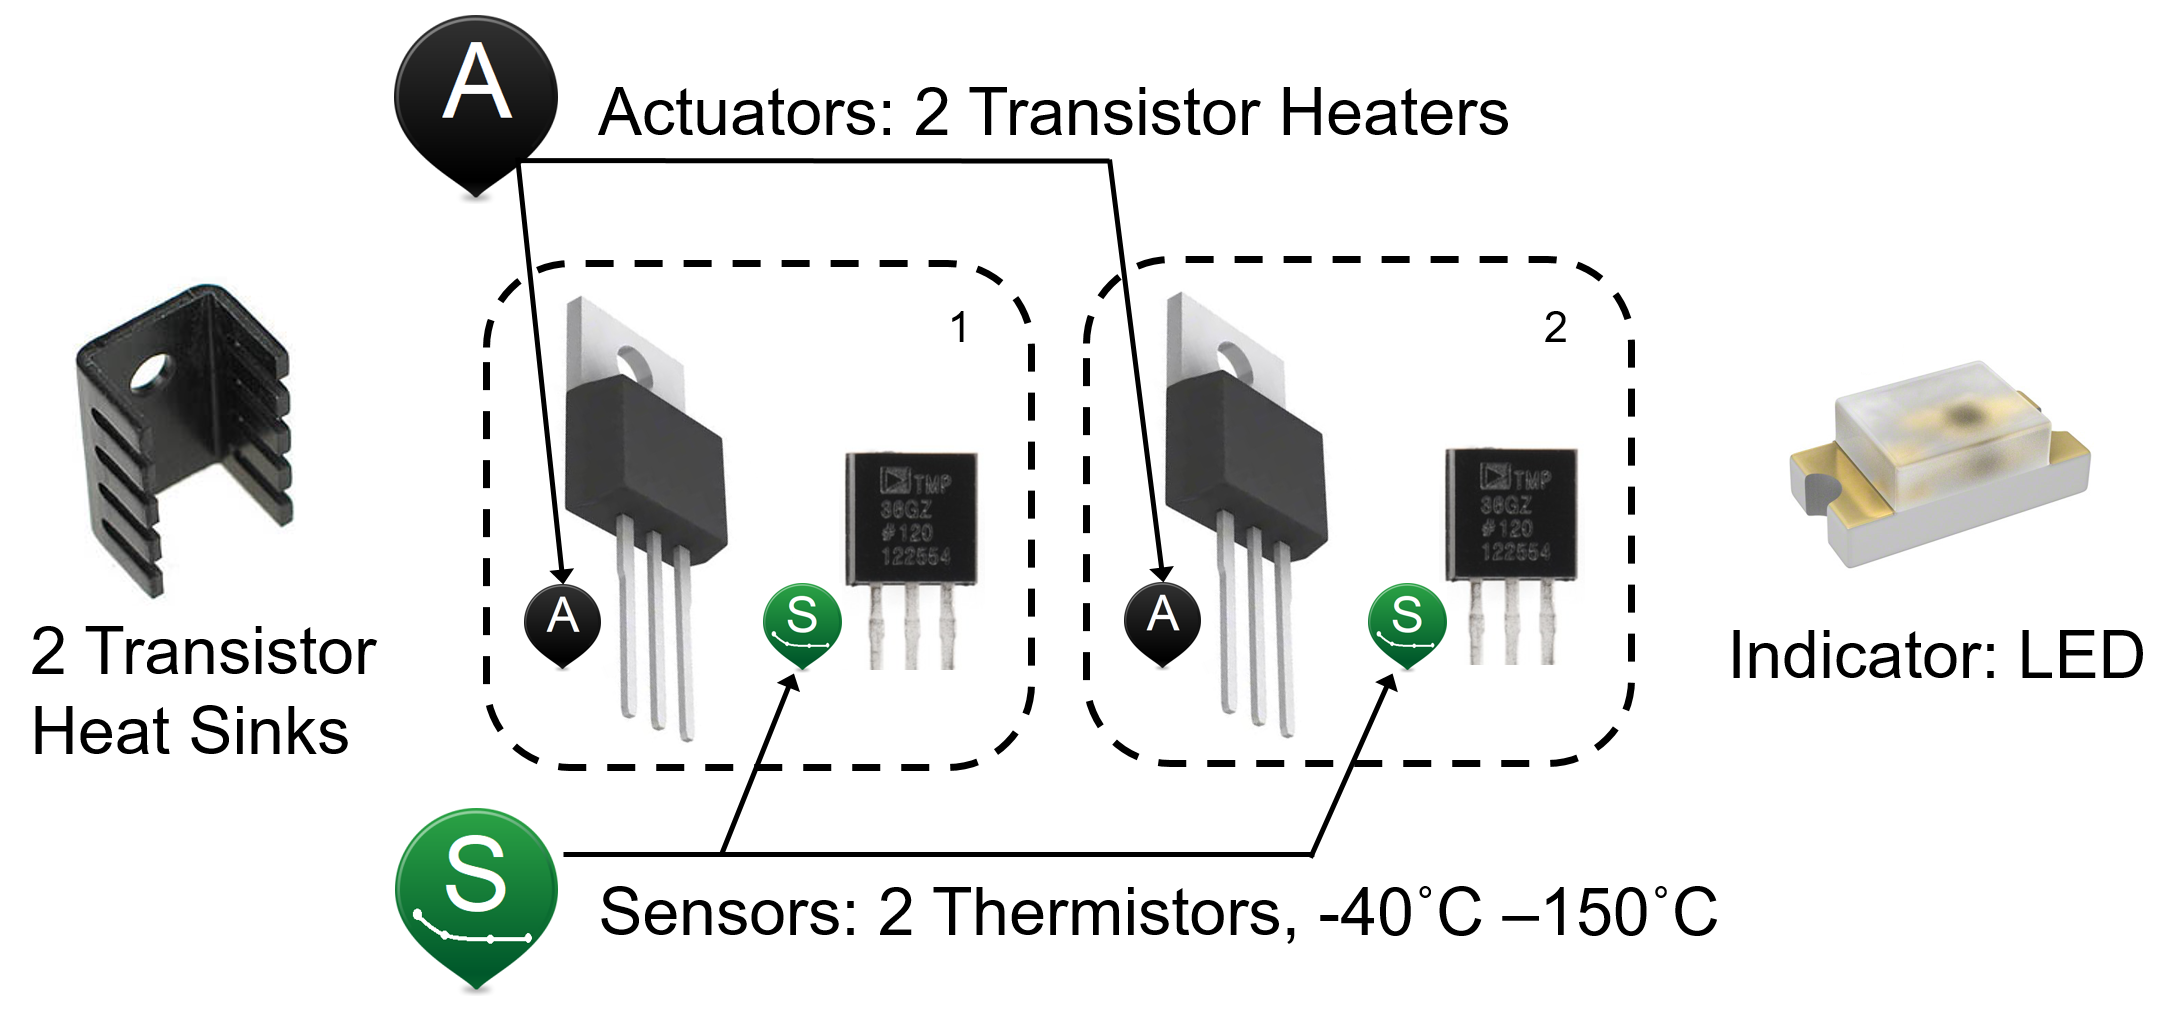

## Regress TCLab Parameters

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);
% Collect data
filename = "Step_Response.csv";
absolute_path = fullfile(directory, filename);

try % try to read from file first
    A = readmatrix(absolute_path)
    tm_ = A(:,1);
    T1_ = A(:,2);
    T2_ = A(:,3);
    Q1_ = A(:,4);
    Q2_ = A(:,5);
    disp('TCLab Data read from file')
    
    figure()
    hold on
    subplot(2,1,1)
    plot(tm_, T1_, 'r.', 'DisplayName','T1')
    hold on
    plot(tm_, T2_, 'b.', 'DisplayName','T2')
    hold off
    legend('Location',"best")
    ylabel('Temperature (C)')
    subplot(2,1,2)
    plot(tm_, Q1_, 'r-','DisplayName','Q1')
    hold on
    plot(tm_, Q2_, 'b-','DisplayName','Q2')
    hold off
    xlabel('Time (sec)')
    ylabel('Heater Setting (%)')
    legend('Location',"best")
    
catch % if file can not be found, simulate
    try 
        n = 600;
        tm_ = zeros(n+1, 1);
        Q1_ = zeros(n+1, 1);
        Q1_(10:200) = 80;
        Q1_(200:280) = 20;
        Q1_(280:400) = 70;
        Q1_(400:end) = 50;
        
        Q2_ = zeros(n+1, 1);
        Q2_(120:320) = 100;
        Q2_(320:520) = 10;
        Q2_(520:end) = 80;
        T1_ = ones(n+1, 1) * 23.0;
        T2_ = ones(n+1, 1) * 23.0;
        % initialize lab
        
        lab = tclab;
        tic;
        figure()
        hold on
        for i=2:n+1
            pause(1-mod(toc,1));
            tm_(i) = toc;
            T1_(i) = lab.T1;
            T2_(i) = lab.T2;
            lab.Q1(Q1_(i));
            lab.Q2(Q2_(i));
            
        
            subplot(2,1,1)
            plot(tm_(1:i), T1_(1:i), 'r.',tm_(1:i), T2_(1:i), 'b.')
            legend({'T1' 'T2'}, 'Location',"best")
            ylabel('Temperature (C)')
            subplot(2,1,2)
            plot(tm_(1:i), Q1_(1:i), 'r-',tm_(1:i), Q2_(1:i), 'b-')
            xlabel('Time (sec)')
            ylabel('Heater Setting (%)')
            legend({'Q1' 'Q2'}, 'Location',"best")
            
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm_, T1_, T2_, Q1_, Q2_]
        writematrix(A, absolute_path, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

use fmincon to perform constrained optimization with bounds. fmincon requires the optimization toolbox. Inequality constraints are passed as $Ax \le b$. To create a lower bound, we use $-x \le b$ for any given lower bound.

% create initial guesses and max/min constraints
% [U, Us, alpha1, alpha2, tau]

x0 = [10, 20, 0.01, 0.005, 10];
A = [-1,0,0,0,0; ...
    1, 0, 0, 0, 0;...
    0, -1, 0, 0, 0;...
    0, 1, 0, 0, 0;...
    0, 0, -1, 0, 0;...
    0, 0, 1, 0, 0;...
    0, 0, 0, -1, 0;...
    0, 0, 0, 1, 0;...
    0, 0, 0, 0, -1;...
    0, 0, 0, 0, 1;
    ];
b = [-1; 20; -5; 40; -0.001; 0.03; -0.001; 0.02; -5; 60 ];
objective(x0, tm_, Q1_, Q2_, T1_, T2_)
soln = fmincon(@(params) objective(params, tm_, Q1_, Q2_, T1_, T2_), x0, A, b)

disp('Parameters:')
disp('U: '+string(soln(1)))
disp('Us: '+string(soln(2)))
disp('alpha1: '+string(soln(3)))
disp('alpha2: '+string(soln(4)))
disp('tau: '+string(soln(5)))
U = soln(1);
Us = soln(2);
alpha1 = soln(3);
alpha2 = soln(4);
tau = soln(5);

T_ = simModel([T1_(1), T2_(1)], tm_, Q1_, Q2_, soln)
T1p = T_(:,1)
T2p = T_(:,2)

figure()
hold on
subplot(2,1,1)
plot(tm_, T1_, 'r.', 'DisplayName','T1')
hold on
plot(tm_, T2_, 'b.', 'DisplayName','T2')
hold on
plot(linspace(0, max(tm_), length(T1p)), T1p, 'r-', 'DisplayName','T1 Predicted')
hold on
plot(linspace(0, max(tm_), length(T1p)), T2p, 'b-', 'DisplayName','T2 Predicted')
hold off
legend('Location',"best")
ylabel('Temperature (C)')
subplot(2,1,2)
plot(tm_, Q1_, 'r-','DisplayName','Q1')
hold on
plot(tm_, Q2_, 'b-','DisplayName','Q2')
hold off
xlabel('Time (sec)')
ylabel('Heater Setting (%)')
legend('Location',"best")

## Simulate System with State Space Model

A physics-based model is developed in prior exercises. A 2nd-order physics-based model consists of four differential equations from energy balances that include convection, conduction, and thermal radiation.


$$m\,c_p\frac{dT_{H1}}{dt} = U\,A\,\left(T_\infty-T_{H1}\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T_{H1}^4\right) + Q_{C12} + Q_{R12} + \alpha_1 Q_1$$



$$m\,c_p\frac{dT_{H2}}{dt} = U\,A\,\left(T_\infty-T_{H2}\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T_{H2}^4\right) - Q_{C12} - Q_{R12} + \alpha_2 Q_2$$



$$\tau \frac{dT_{C1}}{dt} = T_{H1} - T_{C1}$$



$$\tau \frac{dT_{C2}}{dt} = T_{H2} - T_{C2}$$


with the following heat transfer terms for simplifying the expressions.


$$Q_{C12} = U_s \, A_s \, \left(T_{H2}-T_{H1}\right)$$



$$Q_{R12} = \epsilon\,\sigma\,A_s\,\left(T_{H2}^4-T_{H1}^4\right)$$



$$\tau = \frac{m_s \, c_{p,s} \, \Delta x}{k\,A_c}$$


Use these equations to develop a state space model of the temperature response to heater changes.


$$\left[ \matrix{
\dot{T}'_{H1} \cr
\dot{T}'_{H2} \cr
\dot{T}'_{C1} \cr
\dot{T}'_{C2}
} \right] = 
\left[ \matrix{
a_{1,1} & a_{1,2} & a_{1,3} & a_{1,4} \cr
a_{2,1} & a_{2,2} & a_{2,3} & a_{2,4} \cr
a_{3,1} & a_{3,2} & a_{3,3} & a_{3,4} \cr
a_{4,1} & a_{4,2} & a_{4,3} & a_{4,4} 
} \right]
\left[ \matrix{
T'_{H1} \cr
T'_{H2} \cr
T'_{C1} \cr
T'_{C2}
} \right] +
\left[\matrix{
b_{1,1} & b_{1,2} \cr
b_{2,1} & b_{2,2} \cr
b_{3,1} & b_{3,2} \cr
b_{4,1} & b_{4,2} \cr
} \right ]
\left[\matrix{
Q'_1 \cr Q'_2
} \right ]$$



$$\left[\begin{array}{c}
T_{C 1}^{\prime} \\
T_{C 2}^{\prime}
\end{array}\right]=\left[\begin{array}{llll}
0 & 0 & 1 & 0 \\
0 & 0 & 0 & 1
\end{array}\right]\left[\begin{array}{c}
T_{H 1}^{\prime} \\
T_{H 2}^{\prime} \\
T_{C 1}^{\prime} \\
T_{C 2}^{\prime}
\end{array}\right]+\left[\begin{array}{ll}
0 & 0 \\
0 & 0
\end{array}\right]\left[\begin{array}{l}
Q_{1}^{\prime} \\
Q_{2}^{\prime}
\end{array}\right]$$


This state space model:


$$\dot{x}=A x+B u \\y=C x+D u
\end{aligned}$$


has four matrices with $A$ and $B$ that need to be obtained from partial derivatives of the right hand side of the differential equations.


$$
A \in \mathbb{R}^{4 \times 4}=\left[\begin{array}{cccc}
a_{1,1} & a_{1,2} & a_{1,3} & a_{1,4} \\
a_{2,1} & a_{2,2} & a_{2,3} & a_{2,4} \\
a_{3,1} & a_{3,2} & a_{3,3} & a_{3,4} \\
a_{4,1} & a_{4,2} & a_{4,3} & a_{4,4}
\end{array}\right] \\
B \in \mathbb{R}^{4 \times 2}=\left[\begin{array}{cc}
b_{1,1} & b_{1,2} \\
b_{2,1} & b_{2,2} \\
b_{3,1} & b_{3,2} \\
b_{4,1} & b_{4,2}
\end{array}\right] \\
C \in \mathbb{R}^{2 \times 4}=\left[\begin{array}{llll}
0 & 0 & 1 & 0 \\
0 & 0 & 0 & 1
\end{array}\right] \\
D \in \mathbb{R}^{2 \times 2}=\left[\begin{array}{ll}
0 & 0 \\
0 & 0
\end{array}\right]
$$


The individual elements are obtained by evaluating partial derivatives of the differential equations at steady state conditions.


$$
a_{1,1}=\left.\frac{\partial f_{1}}{\partial T_{H 1}}\right|_{\bar{T}}=-\frac{U A+4 \epsilon \sigma A T_{0}^{3}+U_{s} A_{s}+4 \epsilon \sigma A_{s} T_{0}^{3}}{m C_{p}} \\
a_{1,2}=\left.\frac{\partial f_{1}}{\partial T_{H 2}}\right|_{\bar{T}}=\frac{U_{s} A_{s}+4 \epsilon \sigma A_{s} T_{0}^{3}}{m C_{p}}
$$


The following elements will be have nonzero values: $a_{1,1}\ a_{1,2}\ a_{2,1}\ a_{2,2}\ a_{3,1}\ a_{3,3}\ a_{4,2}\ a_{4,4}\ b_{1,1}\ b_{2,2}\ c_{1,3}\ c_{2,4}$

The Cariablea `c1`, `c2`,` c3`, `c4`, `c5`,`c6` have been created for your convenience and` a11` and `a12` have been filled in as examples.

% Constants
Ta =20.0+273.15;                     % K
mass = 4.0/1000.0;                   % kg
Cp = 0.5*1000.0;                     % J/kg-K    
A = 10.0/100.0^2;                    % Area not between heaters in m^2
As = 2.0/100.0^2;                    % Area between heaters in m^2
eps = 0.9;                           % Emissivity
sigma = 5.67e-8;                     % Stefan-Boltzmann

T0 = Ta;
c1 = U*A;
c2 = 4*eps*sigma*A*T0.^3;
c3 = Us*As;
c4 = 4*eps*sigma*As*T0.^3;
c5 = mass*Cp;
c6 = 1/tau;

a11 =  
a12 =  

a21 =  
a22 =  

a31 =  
a33 =  

a42 =  
a44 =  

b11 =  
b22 =  

c13 =  
c24 =  

Create a State Space Model of the TCLab

A = zeros(4);
A(1,1) = a11;
A(1,2) = a12;
A(2,1) = a21;
A(2,2) = a22;
A(3,1) = a31;
A(3,3) = a33;
A(4,2) = a42;
A(4,4) = a44;

B = zeros(4,2);
B(1,1) = b11;
B(2,2) = b22;

C = zeros(2,4)
C(1,3) = c13;
C(2,4) = c24;

D = zeros(2,2)

Simulate Steptest in State Space Model

sys = ss(A, B, C, D);
u = [Q1_, Q2_],
Ta = 23.0
x0 = [Ta; Ta; Ta; Ta]
t = linspace(0, max(tm_), 601)
y = lsim(sys, u, t)

Plot the Simulated State Space Model Compared to the TCLab Data

T1_SS = y(:,1) + T1_(2)
T2_SS = y(:,2) + T2_(2)

figure()
hold on
subplot(2,1,1)
plot(tm_, T1_, 'r.', 'DisplayName','T1')
hold on
plot(tm_, T2_, 'b.', 'DisplayName','T2')
hold on
plot(t, T1_SS, 'r-', 'DisplayName','T1 Predicted')
hold on
plot(t, T2_SS, 'b-', 'DisplayName','T2 Predicted')
hold off
legend('Location',"best")
ylabel('Temperature (C)')
subplot(2,1,2)
plot(tm_, Q1_, 'r-','DisplayName','Q1')
hold on
plot(tm_, Q2_, 'b-','DisplayName','Q2')
hold off
xlabel('Time (sec)')
ylabel('Heater Setting (%)')
legend('Location',"best")

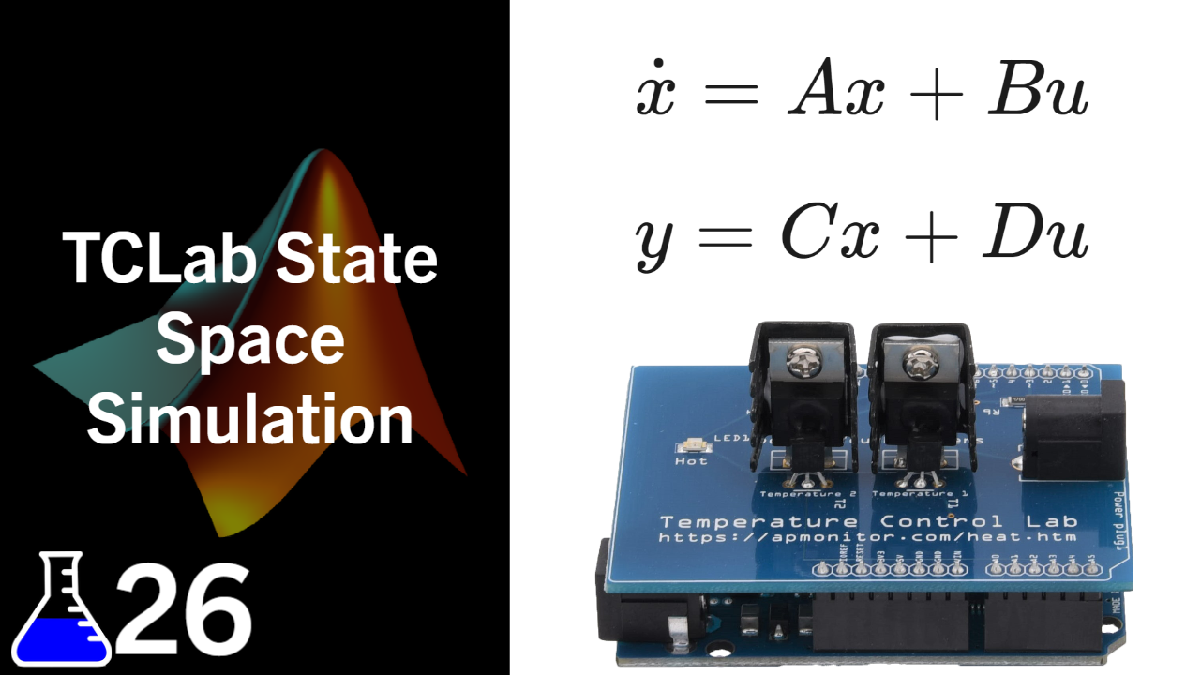

### [View Solution](https://youtu.be/xkZS2Q10ulg)

function dTdt = model(~  ,T,  Q1, Q2, params)
    % unpack states
    TH1 = T(1);
    TH2 = T(2);
    TC1 = T(3);
    TC2 = T(4);
    
    % Unpack Regressed Constants
    U = params(1);
    Us = params(2);
    alpha1 = params(3);
    alpha2 = params(4);
    tau = params(5);
    
    % Constants
    Ta =20.0+273.15;                     % K
    mass = 4.0/1000.0;                   % kg
    Cp = 0.5*1000.0;                     % J/kg-K    
    A = 10.0/100.0^2;                    % Area not between heaters in m^2
    As = 2.0/100.0^2;                    % Area between heaters in m^2
    eps = 0.9;                           % Emissivity
    sigma = 5.67e-8;                     % Stefan-Boltzmann
    
    % Heater Temperatures in Kelvin
    T1 = TH1 + 273.15;
    T2 = TH2 + 273.15;
    
    % Heat transfer between two heaters
    Q_C12 = Us*As*(T2-T1);  % Convective
    Q_R12 = eps*sigma*As*(T2^4-T1^4);  % Radiative
    
    % Calculate derivative values
    TH1dt = (1.0/(mass*Cp))*(U*A*(Ta-T1) ...
                + eps * sigma * A * (Ta^4 - T1^4) ...
                + Q_C12 + Q_R12 ...
                + alpha1*Q1);
    TH2dt = (1.0/(mass*Cp))*(U*A*(Ta-T2) ...
                + eps * sigma * A * (Ta^4 - T2^4) ...
                - Q_C12 - Q_R12 ...
                + alpha2*Q2);
    TC1dt = (TH1 - TC1)/tau;
    TC2dt = (TH2 - TC2)/tau;
    
    dTdt = [TH1dt; TH2dt; TC1dt; TC2dt];
end

function T_ = simModel(T0, tm_, Q1_, Q2_, params)
    n = length(tm_);
    TH1sim_ = ones(n, 1) * T0(1);
    TH2sim_ = ones(n, 1) * T0(2);
    TC1sim_ = ones(n, 1) * T0(1);
    TC2sim_ = ones(n, 1) * T0(2);
    
    T0 = [TH1sim_(1); TH2sim_(1); TC1sim_(1); TC2sim_(1)];
    for i=1:n-1
        ts = [tm_(i) tm_(i+1)];
        [~,T] = ode45(@( t,T) model(t,T,  Q1_(i), Q2_(i), params), ts, T0);
        T0 = T(end,:);
        TH1sim_(i+1) = T0(1);
        TH2sim_(i+1) = T0(2);
        TC1sim_(i+1) = T0(3);
        TC2sim_(i+1) = T0(4);
    end
    T_ = [TH1sim_, TH2sim_];
end

function sse = objective(params, tm_, Q1_, Q2_, T1m_, T2m_)
    Tsim = simModel([T1m_(1), T2m_(1)], tm_, Q1_, Q2_, params);
    
    sse = sum((Tsim(:,1) - T1m_).^2) + sum((Tsim(:,2) - T2m_).^2);
end

function viewSolution(view)
if view
	disp("a11 = -(c1+c2+c3+c4)/c5" + newline + ...
	     "a12 = (c3+c4)/c5" + newline + ...
	     "" + newline + ...
	     "a21 = (c3+c4)/c5" + newline + ...
	     "a22 = -(c1+c2+c3+c4)/c5" + newline + ...
	     "" + newline + ...
	     "a31 = c6" + newline + ...
	     "a33 = -c6" + newline + ...
	     "" + newline + ...
	     "a42 = c6" + newline + ...
	     "a44 = -c6" + newline + ...
	     "" + newline + ...
	     "b11 = alpha1/c5" + newline + ...
	     "b22 = alpha2/c5" + newline + ...
	     "" + newline + ...
	     "c13 = 1")
end
end
